# **TALLERES 13-14-15 MODELO DE UN PENDULO SIMPLE CON FUERZA TANGENCIAL  **

***Presentado por*****: ***Sara García Behaine*

*Ecuaciones diferenciales *

*Ingeniería Civil*

*Eafit  *

*13-Agosto-2023*

***OBJETIVO*** 

Resolver numéricamente la ecuación de estado no lineal de un péndulo simple en un archivo Live Script de MATLAB e interpretar los resultados cambiando diversos parámetros a partir de la respuesta temporal y retrato de fase.

***INTRODUCCIÓN: ***

En este taller, vamos a estudiar el comportamiento dinámico de un péndulo simple con fuerza tangencial. El péndulo está formado por una masa puntual m, unida a un hilo de longitud L. La fuerza tangencial **u** es aplicada por un motor o un dispositivo externo. **θ** es el ángulo del péndulo respecto a la posición vertical (en radianes), **ω **es la velocidad angular del péndulo (en radianes por segundo), **u **es la fuerza tangencial (en newtons),** L** es la longitud del péndulo (en metros),** f** es el coeficiente de fricción viscosa (en newtons por metro por segundo), **g** es la aceleración de la gravedad (en metros por segundo cuadrado). En este taller, vamos a resolver numéricamente la ecuación diferencial para diferentes valores de los parámetros. También vamos a graficar  los retratos de fase del sistema para diferentes condiciones iniciales.

Las actividades que vamos a realizar son las siguientes:

- Resolver numéricamente la ecuación diferencial y graficar las soluciones temporales con una entrada u = 1.

- Trazar la curva de linealidad del sistema.

- Dibujar el retrato de fase para diferentes condiciones iniciales.

- Explicar el efecto de los parámetros del péndulo en su comportamiento dinámico.

**MÉTODOS A USAR:**

- *Usaré elementos teóricos dictados en clases, los usaré como ejemplo para la solución de la ecuación diferencial y de todas las actividades entregables*

- *Método deductivo (mirar la parte teórica y a partir de lo que matlab arroje, analizarlo y dar una posible interpretación)*

- *En matlab, emplearé diversas funciones que me ayudarán a crear mis codigos y posteriormente a darles solución; primeramente ****(syms)****, la cuál me permitirá declarar las variables simbólicas de los diferentes ejercicios, ***OdeFunction*** (*resuelven problemas de valores iniciales con una gran variedad de propiedades), ***ode45**** (el cual nos ayuda a *comparar métodos de orden cuatro y cinco para estimar el error y determinar el tamaño del paso), **h** (es el paso del tiempo)** tmin:** (que es el tiempo minimo o inicial del sistema)** tmax**: (que es el tiempo maximo o final del sistema)**, tspan** (que es el vector de elementos temporales iniciales y finales, o más bien, es el vector temporal del sistema), también usaré herramientas como** (plot, grid on, title, x label, y label, legends**, los cuales me serán de ayuda para hacer graficos y embellecerlos, para obtener información que me sea de ayuda en los diferentes gráficos), también haré uso de **for **y** end **que se emplean para crear bucles que permiten repetir un conjunto de instrucciones un número especifico de veces. 

**DESCRIPCIÓN DEL MODELO:**

Dada la siguiente la siguiente **ecuación de estado** de **segundo orden no lineal** de un modelo de un **péndulo simple con fuerza tangencial,** resolverla utilizando el método numérico de Runge-Kutta implementado en la función **ode45** de MATLAB. 

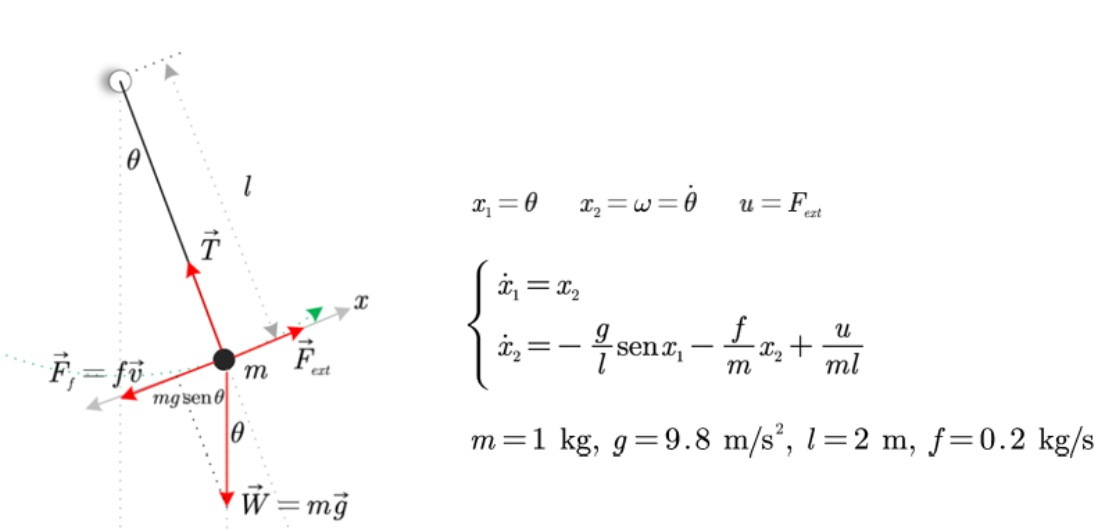

Donde, θ es el ángulo (en radianes, rad) respecto a la posición vertical, ω es la velocidad angular (en radianes por segundo, rad/s) y *u* es la fuerza externa aplicada tangencialmente. Los parámetros son la masa (*m*, en kilogramos), la longitud (*l*, en metros), la aceleración de la gravedad (*g*, en m/s2) y f es el coeficiente de fricción viscosa (*f*, N/(ms-1) o kg/s). Suposición: el hilo es rígido y tiene una masa que se puede despreciar, por lo que el péndulo puede tomar posiciones superiores.

**PUNTO 1:  **Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones temporales con una entrada u = 1. ¿Para qué valor máximo de la entrada el sistema rotará indefinidamente? 

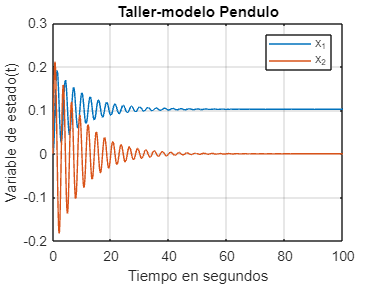

syms x1(t) x2(t) %Defino las variables de estado
%Defino el nombre y valor de las variables 
m=1;  %Masa en Kg
g=9.8; %Aceleración de la gravedad
l=2; %Longitud en metros 
f=0.2; %Fricción viscosa
u=1;%4702180003; Fuerza Externa 
ci = [0,0]; %Defino condiciones iniciales desde el reposo 

% Defino las ecuaciones de estado para el pendulo
f1 = x2;
f2 = u/(m*l)-(g/l)*sin(x1)-(f/m)*x2;
F = odeFunction([f1 f2],[x1 x2]); % usamos el comando ODEFunction para resolver
tmin=0; %Tiempo minimo o inicial del sistema
tmax=100; %Tiempo maximo o final del sistema
ts= tmin:0.1:tmax; % Tiempo de muestreo

[ts,sol]=ode45(F,ts,ci);

%A continuación graficaremo:
figure
plot(ts,sol)
legend({'x_1','x_2'})
syms x1(t) x2(t)
xlabel('Tiempo en segundos');
ylabel('Variable de estado(t)');
title('Taller-modelo Pendulo')
grid on 

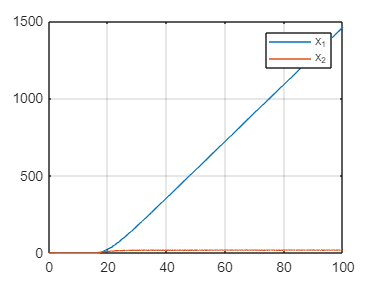

m=1;
g=9.8;
l=2;
f=0.2;
u=7.54702180005;
ci = [0,0];

f1 = x2;
f2 = u/(m*l)-(g/l)*sin(x1)-(f/m)*x2;
F = odeFunction([f1 f2],[x1 x2]); 
tmin=0;
tmax=100;
ts= tmin:0.1:tmax;

[ts,sol]=ode45(F,ts,ci);

figure
plot(ts,sol)
grid on
legend({'x_1','x_2'})

**PUNTO 2:** Trazar la curva de linealidad, es decir, el valor en el que se estabiliza el péndulo en función del valor de la entrada. El rango de entradas no debe superar el valor máximo calculado anteriormente.

curva_linealidad = zeros(76,2);
%0:0.1:7.5
U=0:0.1:7.5

U =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


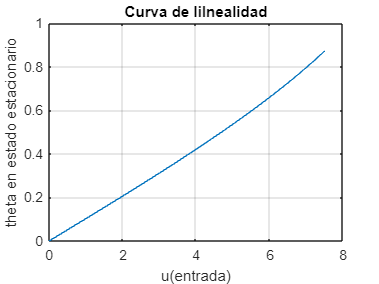

for i = 1:length(U) %cuantos datos son
    u=U(i);
    f1 = x2;
    f2 = u/(m*l)-(g/l)*sin(x1)-(f/m)*x2;
    F = odeFunction([f1 f2],[x1 x2]);
    [ts,sol]=ode45(F,ts,ci);
    curva_linealidad(i,1)=u;
    curva_linealidad(i,2)=sol(end,1);
end
plot(curva_linealidad(:,1),curva_linealidad(:,2))
grid on
title('Curva de lilnealidad')
xlabel('u(entrada)')
ylabel('theta en estado estacionario')

**PUNTO 3: **Dibujar el retrato de fase para un cambio en la condición inicial de la velocidad angular entre 3 y 6 rad/s con incrementos de 0.5 rad/s. Interpretar el resultado. ¿Para qué valor de la frecuencia angular inicial el péndulo da una vuelta? ¿Para qué valor da tres vueltas? Observar los puntos de equilibrio.

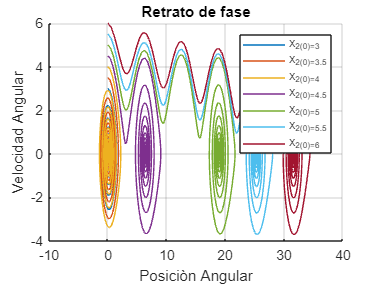

syms x1(t) x2(t) %Defino las variables de estado
%Defino las variables a continuación:
m=1; %Masa kg
g=9.8; %Aceleración de la gravedad
l=2; %Longitud en metros
f=0.2; %Fricción viscosa
u=1;%Fuerza externa 

% Defino las ecuaciones de estado
f1 = x2;
f2 = u/(m*l)-(g/l)*sin(x1)-(f/m)*x2;
F = odeFunction([f1 f2],[x1 x2]);
%Defino tiempo minimo y maximo del sistema, con tiempo de muestreo 
tmin=0;
tmax=100;
ts= tmin:0.1:tmax;

VA = 3:0.5:6; %Velocidad angular de 3 a 6 radianes con
%incremento de o.5 rad/s
p_eq = zeros(7,2); 

%Graficamos el retrato de fase
figure
hold on
for i = 1:length(VA)
    ci = [0,VA(i)];
    [ts,sol]=ode45(F,ts,ci);
    plot(sol(:,1),sol(:,2))
    p_eq(i,1)=sol(end,1);
    p_eq(i,2)=sol(end,2);
end
xlabel('Posiciòn Angular')
ylabel('Velocidad Angular')
title('Retrato de fase')
legend({'x_2(0)=3','x_2(0)=3.5','x_2(0)=4','x_2(0)=4.5','x_2(0)=5','x_2(0)=5.5','x_2(0)=6'})
grid on
hold off

p_eq

p_eq =     0.1022    0.0001
    0.1021    0.0000
    0.1022   -0.0002
    6.3855    0.0003
   18.9516   -0.0002
   25.2351    0.0005
   31.5181   -0.0007


**PUNTO 4: **Dibujar el retrato de fase para un cambio en la condición inicial de la posición angular entre -6 y 6 rad con incrementos de 0.5 rad. Interpretar el resultado. Observar los tres únicos puntos de equilibrio.

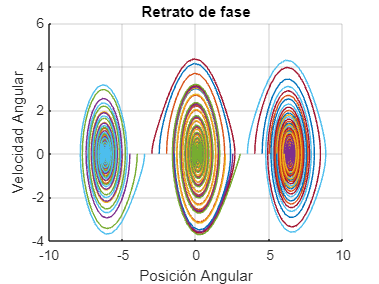

syms x1(t) x2(t) %Definimos variables de estado 
%Definimos variables y sus valores
m=1; %Masa en kg
g=9.8; %Aceleración de la gravedad
l=2; %Longitud en metros
f=0.2;%Fricción viscosa
u=1; %Fuerza externa 

%Definimos las ecuaciones de estado:
f1 = x2;
f2 = u/(m*l)-(g/l)*sin(x1)-(f/m)*x2;
F = odeFunction([f1 f2],[x1 x2]);
%Definimos tiempo maximo, mínimo y tiempo de muestreo 
tmin=0;
tmax=100;
ts= tmin:0.1:tmax;

PA = -6:0.5:6; %Posición angular variando entre -6 y 6 radianes,
%con incremento de 0.5 rad/s
p_eq = zeros(25,3); 
%Graficamos nuestro sistema:
figure
hold on
for i = 1:length(PA)
    ci = [PA(i),0];
    [ts,sol]=ode45(F,ts,ci);
    plot(sol(:,1),sol(:,2))
    p_eq(i,1)=PA(i);
    p_eq(i,2)=sol(end,1);
    p_eq(i,3)=sol(end,2);
end
xlabel('Posición Angular')
ylabel('Velocidad Angular')
title('Retrato de fase')
%legend({'','x_2(0)=3.5','x_2(0)=4','x_2(0)=4.5','x_2(0)=5','x_2(0)=5.5','x_2(0)=6'})
grid on
hold off

p_eq

p_eq =    -6.0000   -6.1810   -0.0000
   -5.5000   -6.1809   -0.0000
   -5.0000   -6.1809    0.0000
   -4.5000   -6.1809    0.0001
   -4.0000   -6.1810    0.0002
   -3.5000   -6.1811   -0.0001
   -3.0000    0.1021   -0.0000
   -2.5000    0.1023    0.0002
   -2.0000    0.1023   -0.0001
   -1.5000    0.1022   -0.0001


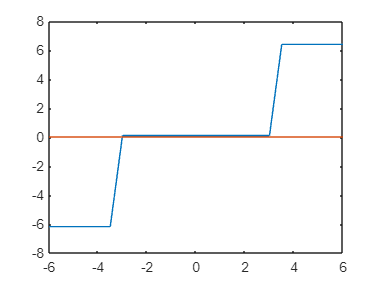

plot(p_eq(:,1),p_eq(:,[2,3]))

**PUNTO 5: ** Explicar el efecto del cambio de la longitud del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

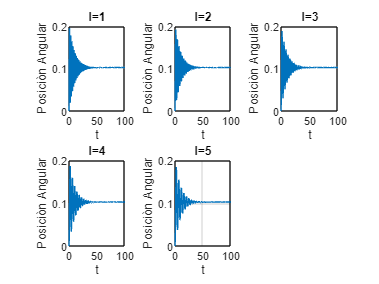

syms x1(t) x2(t) %Definimos las variables de estado x1 y x2
%Definimos las constantes 
m=1; %Masa en kg
g=9.8; %Aceleración de la gravedad 
%l=2; longitud en metros, que es la que variaremos
f=0.2;%Fricción viscosa
u=1; %Fuerza externa 

%Definimos el tiempo maximo, minimo, tiempo de muestreo y condiciones 
%iniciales iguales a cero
tmin=0;
tmax=100;
ts= tmin:0.1:tmax;
ci = [0,0];

L = 1:1:5; %Variaremos la longitud del pendulo desde 1-5
%p_eq = zeros(25,3); 
figure
%hold on
for i = 1:length(L)
    l = L(i);
    f1 = x2;
    f2 = u/(m*l)-(g/l)*sin(x1)-(f/m)*x2;
    F = odeFunction([f1 f2],[x1 x2]);

    [ts,sol]=ode45(F,ts,ci);
    subplot(2,3,i)
    plot(ts,sol(:,1))
    %p_eq(i,1)=PA(i);
    %p_eq(i,2)=sol(end,1);
    %p_eq(i,3)=sol(end,2);
    xlabel('t')
    ylabel('Posiciòn Angular')
    title('l='+string(L(i)))
end
grid on
hold off

**PUNTO 6: **Explicar el efecto del cambio de la masa del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

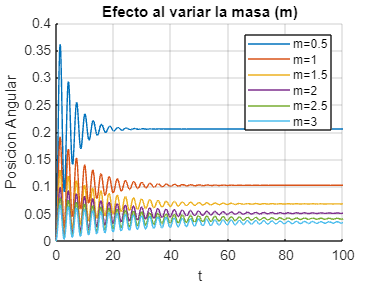

syms x1(t) x2(t) %Definimos variables de estado 
%Definimos las constantes 
%m=1; masa en kg, que es la que vamos a variar 
g=9.8; %Aceleración de la gravedad 
l=2; %Longitud en metros 
f=0.2; %Fricción viscosa
u=1; %Fuerza externa 

%Definimos el tiempo maximo, minimo y de muestreo, con las condiciones
%iniciales iguales a cero
tmin=0;
tmax=100;
ts= tmin:0.1:tmax;
ci = [0,0];

M = 0.5:0.5:3; %Variaremos la masa (M), desde 0.5-3
%p_eq = zeros(25,3); 
figure
hold on
for i = 1:length(M)
    m = M(i);
    f1 = x2;
    f2 = u/(m*l)-(g/l)*sin(x1)-(f/m)*x2;
    F = odeFunction([f1 f2],[x1 x2]);

    [ts,sol]=ode45(F,ts,ci);
    %subplot(2,3,i)
    plot(ts,sol(:,1))
    %p_eq(i,1)=PA(i);
    %p_eq(i,2)=sol(end,1);
    %p_eq(i,3)=sol(end,2);
    xlabel('t')
    ylabel('Posicion Angular')

end
grid on
legend({'m=0.5','m=1','m=1.5','m=2','m=2.5','m=3'})
    title('Efecto al variar la masa (m)')
hold off

**PUNTO 7:  **Explicar el efecto del cambio de la fricción viscosa del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

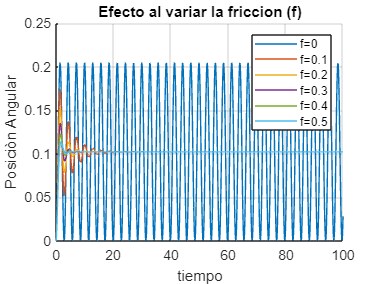

syms x1(t) x2(t) %Definimos variables de estado
%Definimos constantes 
m=1; %Masa en kg 
g=9.8;%Aceleración de la gravedad 
l=2; %Longitud en metros 
%f=0.2; %Fricción viscosa, que es lo que variaremos  
u=1; %Fuerza externa 

%Definimos tiempo maximo, minimo, de muestreo y condiciones
%iniciales iguales a cero
tmin=0;
tmax=100;
ts= tmin:0.1:tmax;
ci = [0,0];

Fr = 0:0.5:2.5; %Coeficiente de fricción viscosa, el cual 
%variaremos dede 0-0.5
%p_eq = zeros(6,3); 
figure
hold on
for i = 1:length(Fr)
    f = Fr(i);
    f1 = x2;
    f2 = u/(m*l)-(g/l)*sin(x1)-(f/m)*x2;
    F = odeFunction([f1 f2],[x1 x2]);

    [ts,sol]=ode45(F,ts,ci);
    %subplot(2,3,i)
    plot(ts,sol(:,1))
    %p_eq(i,1)=PA(i);
    %p_eq(i,2)=sol(end,1);
    %p_eq(i,3)=sol(end,2);
    xlabel('tiempo')
    ylabel('Posiciòn Angular')

end
grid on
legend({'f=0','f=0.1','f=0.2','f=0.3','f=0.4','f=0.5'})
    title('Efecto al variar la friccion (f)')
hold off

**PUNTO 8:** Si f = 0, u = 0 (movimiento libre no amortiguado) y la posición angular inicial ω(0) es menor a unos 30° (0.5 radianes, aproximadamente), se puede aproximar el seno del ángulo en radianes por el ángulo (comprobar con la calculadora o MATLAB) y el modelo es lineal. Obtener la ecuación de estado, pasar a la ecuación diferencial homogénea con coeficientes constantes y resolverla analíticamente. ¿Cómo se puede medir la aceleración de la gravedad si se conoce la longitud? ¿Cómo se puede obtener la longitud si se conoce la aceleración de la gravedad? Comprobar los resultados con MATLAB.

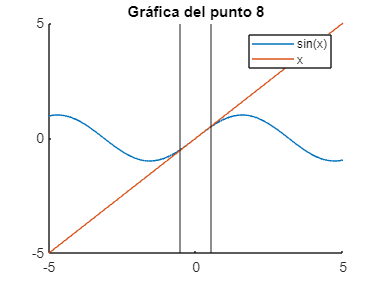

syms x %Variable x
figure %Graficamos
hold on
fplot(sin(x))
fplot(x)
xline(-pi/6)
%xline(-0.5)
%xline(0.5)
xline(pi/6)
legend({'sin(x)','x'})
title('Gráfica del punto 8')
hold off

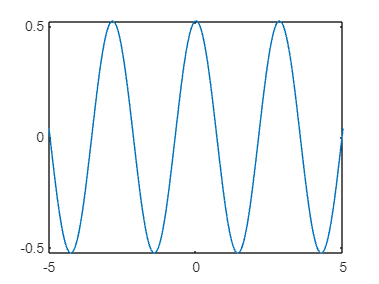

syms t %Variable temporal 
g=9.8; %Aceleración de la gravedad 
l=2; %Longitud en metros 
fplot((pi/6)*cos(sqrt(g/l)*t))

t1 = 2.8379; %Tiempo que tarda en volver a la posiciòn inicial
w = 2*pi/t1 %Frecuencia

w = 2.2140

l_obs = g/(w*w)

l_obs = 1.9992

g_obs = (w*w)*l

g_obs = 9.8038

**PUNTO 9:** Si se conoce la respuesta temporal de un péndulo con fuerza igual a 1 N, *l* = 2 y *g* = 9.8, hallar aproximadamente por tanteo los valores de *f* y *m*. Explicar el procedimiento. Tener en cuenta los resultados de las tareas 6 y 7.

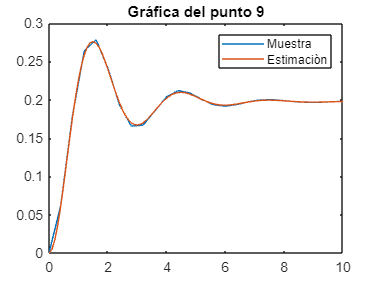

ts = 0:0.4:10; %Tiempo de muestreo 
theta = [0,0.0621,0.1797,0.2635,0.2783,0.2414,0.1932,0.1656,0.1667,0.1852,0.2038,0.2119,0.2086,0.2002,0.1934,0.1915,0.1938,0.1973,0.1997,0.1999,0.1987,0.1972,0.1965,0.1966,0.1972,0.1978];
figure %Graficar y plotear  
plot(ts,theta)
hold on
syms x1(t) x2(t) %Definimos variables de estado 
m=0.52; % Masa en kg a estimar
g=9.8; %Aceleración de la gravedad 
l=2; %Longitud en metros 
f=0.65; % Coeficiente de friccion a estimar
u=1;%4702180003; Fuerza externa
ci = [0,0];%Condiciones iniciales iguales a cero 

%Definimos las ecuaciones de estado:
f1 = x2;
f2 = u/(m*l)-(g/l)*sin(x1)-(f/m)*x2;
F = odeFunction([f1 f2],[x1 x2]);
%Definimos tiempo máximo, mínimo y de muestreo 
tmin=0;
tmax=10;
ts= tmin:0.1:tmax;

[ts,sol]=ode45(F,ts,ci);
plot(ts, sol(:,1))
legend({'Muestra','Estimaciòn'})
title('Gráfica del punto 9')
hold off

# **CONCLUSIONES Y ANÁLISIS**

- Los valores maximos de la posicion angular, son los ceros de la velocidad angular 

- Trazando la curva de linealidad, no se cumple con el principio de superposicion, la curva de linealidad no es una linea recta

-  Se llama el plano de fase por que es en dos dimensiones, la fuerza externa es cero, son dos graficas indivuales de oscilaciones que al pegarlas quedan como un espiral, el cual converge en el punto 0 el cual es la **u** inicial, por la friccion con el fluido hace que se reduzca y tenga su forma de espiral, cada remolino signifca una vuelta completa el cual es 2pi. 

- En este punto, se está simulando el comportamiento dinamico de un pendulo invertido bajo diversas condiciones iniciales, mostrando como varia su comportamiento en un grafico que relaciona la posicion y la velocidad angulares, el retrato de fase en este contexto muestra como varia la posicion angular (x1) y la velocidad angular (x2) del pendulo invertido, variando de -6 a 6 radianes con incremento de 0.5 rad/s, el análisis del retrato de fase puede revelar aspectos como la estabilidad, las órbitas o trayectorias recurrentes del sistema. Por ejemplo, si las trayectorias forman circulos o el sistema regresa a los mismos puntos, estaría representando un comportamiento periodico, y si las trayectorias se alejan o divergen, estaria indicando inestabilidad. 

- Las graficas muestan la posicion angular en funcion del tiempo para cada longitud del pendulo. A medida que cambia la longitud, se observa como la posicion angular evoluciona con el tiempo. Además, variar la longitud del pendulo afecta su comportamiento dinamico, Cuanto mas largo es el pendulo, generalmente toma mas tiempo completar un ciclo de oscilación. Un pendulo mas largo tiende a oscular mas lentamente en comparación con uno mas corto para el mismo rango de desplazamientos angulares. Tambien, cabe aclarar que las condiciones iniciales iguales a cero indican que el pendulo comienza desde el reposo (sin desplazamiento angular inicial o velocidad angular). La fuerza externa se mantiene constante en 1 para las simulaciones. 

- Las graficas muestran posicion angular en funcion del tiempo para cada masa del pendulo. Se observa como la posicion angular evoluciona respecto a diferentes masas, un aumento en la  masa del pendulo, resulta en un cambio en su comportamiento dinamico, en general, una mayor masa tiende a influir en una reducción a la velocidad de oscilación. En otras palabras, a medida que la masa aumenta, el pendulo tiende a oscilar mas lento para el mismo rango de desplazamientos angulares, para una masa de 0,5kg el tiempo de oscilacion es menor que para una masa de 3kg. 

- La grafica muestra la posicion angular en funcion del tiempo para cada coeficiente de preccion del pendulo. Un aumento en el coeficiente de friccion viscosa provoca una disminución en la amplitud de las oscilaciones, es decir, a medida que el coeficiente de friccion aumenta, el pendulo experimenta una mayor resistencia al movimiento, lo que resulta en una reducción en la amplitud del desplazamiento angular a lo largo del tiempo, en la grafica podemos ver que para un coeficiente de friccion viscosa en 0, no hay amplitud, a medida que este aumenta por ejemplo en o,3 la amplitud crece, y para un coeficiente de fricción de 0,5 que es la linea azul cielo de la grafica, vemos que la ampltud es muy grande. 

- Si se conoce la longitud del pendulo y se quiere medir la aceleración de la gravedad, se puede hacer mediante la formula del periodo del pendulo simple que esta determinada por : 

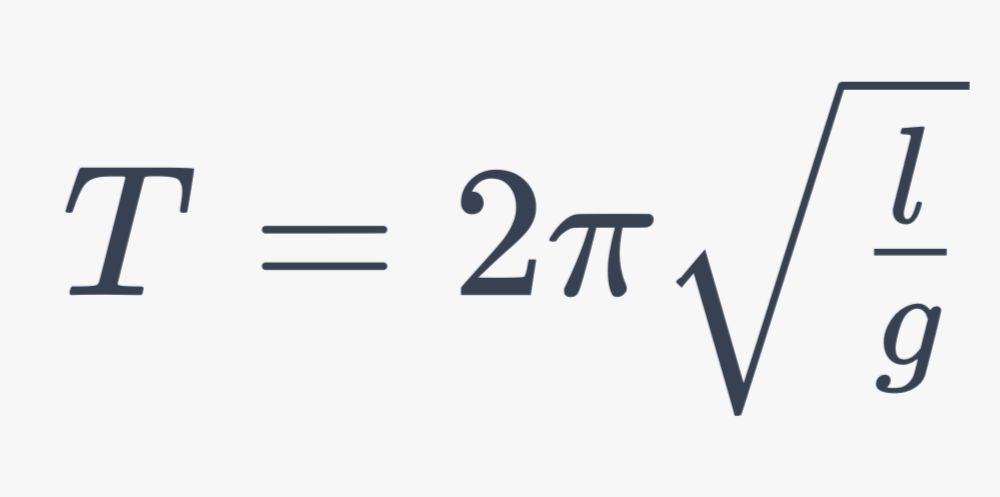

Si se mide el periodo del pendulo, sep puede despejar la aceleración de la gravedad (g) usando la longitud conocida (l) con la formula: 

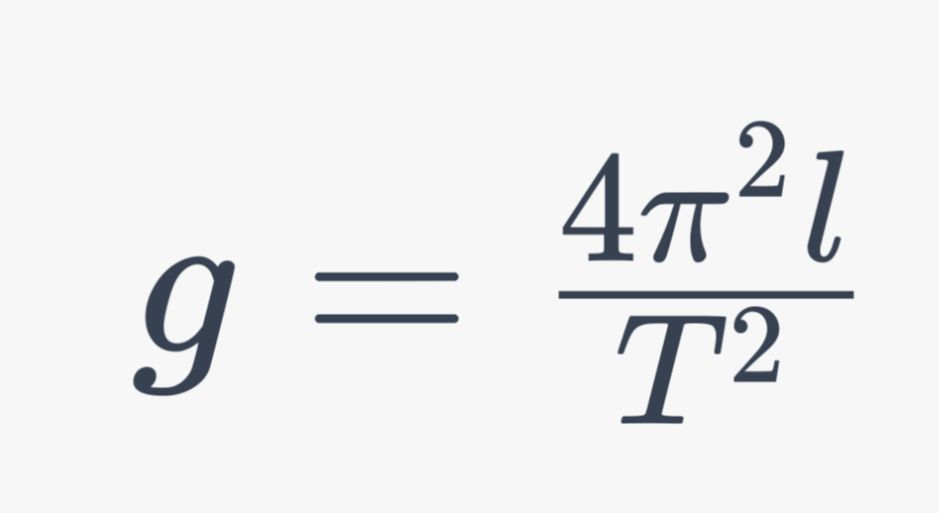

Si por otro lado se conoce la aceleración de la gravedad y se quiere determinar la longitud del pendulo, se puede usar la misma formula, pero despejando la longitud: 

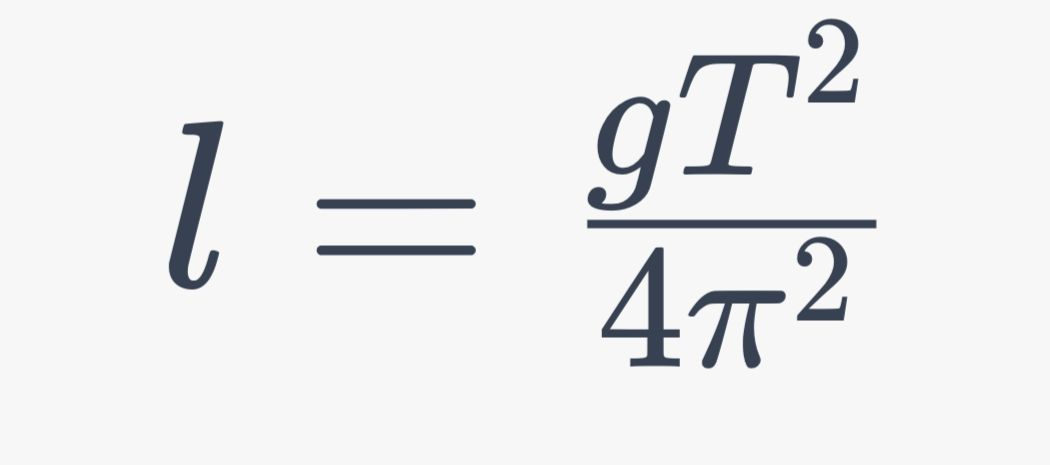

9. Usando el metodo del tanteo, se busca ajustar iterativamente los valores de f y de m para que la solución numérica del modelo del pendulo se aproxime lo mas posible a la respuesta temporal proporcionada. Se inicia con valores estimados, se resuelve el modelo del pendulo y se ajustan manualmente los valores de f yde m hasta lograr una respuesta que se alinee de manera aceptable a la respuesta temporal conocida. Este proceso se repite hasta que se encuentren valores que proporcionen una solución numérica cercana a la respuesta temporal proporcionada. En conclusion los valores de la estimación y de la muestra en la grafica siguen exactamente la misma trayectoria, son casi parecidos, lo que indica que el tanteo mostró resultados equivalentes. 